# Optimization and Data Analytics HW20

## Introduction to Machine Learning Course Notes sec. 5

## Exercise 4.1

The optimal projection matrix **W**, can be calculated by optimizing the criterion:


$$\jmath \left(W\right)=\frac{\mathrm{Tr}\left({\mathit{\mathbf{W}}}^T S_b \mathit{\mathbf{W}}\right)}{\mathrm{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}$$


In order to prove the equivalency, we write:


$$\jmath \left(W\right)+1=\frac{\mathrm{Tr}\left({\mathit{\mathbf{W}}}^T S_b \mathit{\mathbf{W}}\right)}{\mathrm{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}+1=\frac{\mathrm{Tr}\left({\mathit{\mathbf{W}}}^T S_b \mathit{\mathbf{W}}\right)}{\mathrm{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}+\frac{\mathrm{Tr}\left({\mathit{\mathbf{W}}}^T S_w \mathit{\mathbf{W}}\right)}{\mathrm{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}$$


This is valid, since the +1 is a constant and is therefore not a factor to optimize.

By applying the equality $S_T =S_w +S_b$, this may be rewritten to:


$$\j \left(W\right)+1=\frac{\text{Tr}\left({\mathit{\mathbf{W}}}^T S_b \mathit{\mathbf{W}}\right)+\text{Tr}\left({\mathit{\mathbf{W}}}^T S_w \mathit{\mathbf{W}}\right)}{\text{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}=\frac{\text{Tr}\left({\mathit{\mathbf{W}}}^T S_T \mathit{\mathbf{W}}\right)}{\text{Tr}\left(W^T S_w \mathit{\mathbf{W}}\right)}=\frac{1}{\j_2 \left(W\right)}$$


Thus, the LDA criterion $\j \left(W\right)$ may be maximized by minimizing $\j_2 \left(W\right)$ due to the reciprocal.

## Exercise 4.2

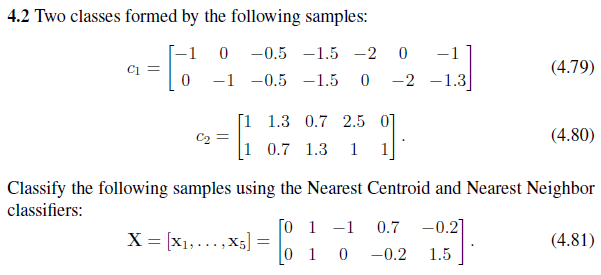

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]

c1 =    -1.0000         0   -0.5000   -1.5000   -2.0000         0   -1.0000
         0   -1.0000   -0.5000   -1.5000         0   -2.0000   -1.3000


[k,NC(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]

c2 =     1.0000    1.3000    0.7000    2.5000         0
    1.0000    0.7000    1.3000    1.0000    1.0000


[k,NC(2)] = size(c2);

X = [0 1 -1 0.7 -0.2;
    0 1 0 -0.2 1.5]

X =          0    1.0000   -1.0000    0.7000   -0.2000
         0    1.0000         0   -0.2000    1.5000


[k,NX] = size(X);

K = 2;

## Nearest Centroid Classifier (NC)

The *nearest centroid *classifier (NC) represents each class $c_k$ with the corresponding mean class vector:


$$\mu_k =\frac{1}{N_k }\sum_{i,l_i =k} x_i \text{   },\text{  }k=1,\ldotp \ldotp \ldotp ,K$$


% Calculate class means along each dimension
mean1 = mean(c1,2)

mean1 =    -0.8571
   -0.9000



mean2 = mean(c2,2)

mean2 =     1.1000
    1.0000


Each sample is then classified to the class corresponding to the smallest distance:


$$d\left(x_\ast  ,\mu_k \right)={\left\|x_\ast  -\mu_k \right\|}_2^2$$


% Calculate euclidean distances from class means
x_c1_dist = sqrt(sum((X-mean1)'.^2, 2))';    % Norm of each column
x_c2_dist = sqrt(sum((X-mean2)'.^2, 2))';    % Norm of each column
nc_dist = [x_c1_dist; x_c2_dist]

nc_dist =     1.2429    2.6569    0.9113    1.7072    2.4883
    1.4866    0.1000    2.3259    1.2649    1.3928



% Classify samples to the nearest centroid
[nc_min_dist,nc_classification] = min(nc_dist)

nc_min_dist =     1.2429    0.1000    0.9113    1.2649    1.3928


nc_classification =      1     2     1     2     2


## Nearest Neighbor Classifier (NN)

The *nearest neighbor* classifier (NN) classifies a sample to class of the sample closest to it.

% Calculate the distance to all class samples
nn_dist = zeros(2,NX);
for i=1:NX
    % Calculate distance to samples of class 1  
    dist_c1 = []; 
    for j=1:NC(1)
       dist_c1(j) = norm(X(:,i)-c1(:,j));
    end
    % Find the nearest class 1 neighbor
    nn_dist(1,i) = min(dist_c1);
    
    % Calculate distance to samples of class 2  
    dist_c2 = []; 
    for j=1:NC(2)
       dist_c2(j) = norm(X(:,i)-c2(:,j));
    end
    % Find the nearest class 2 neighbor
    nn_dist(2,i) = min(dist_c2);
end
nn_dist

nn_dist =     0.7071    2.1213         0    1.0630    1.7000
    1.0000         0    1.4142    1.0817    0.5385



% Classify samples to the nearest neighbor
[nn_min_dist,nn_classification] = min(nn_dist)

nn_min_dist =     0.7071         0         0    1.0630    0.5385


nn_classification =      1     2     1     1     2


## Exercise 4.3

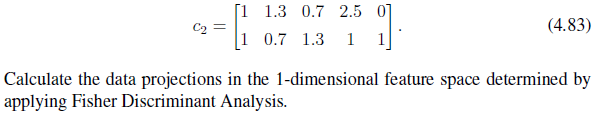

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]
[k,NC(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]
[k,NC(2)] = size(c2);

In order to determine the LDA, the *within-class* scatter matrix $S_w$ and *between-class* scatter matrix $S_b$ must be calculated.

The first step is calculating the mean vector of each class, and the total mean vector:

mean_total = mean([c1 c2],2);
mean1 = mean(c1,2);
mean2 = mean(c2,2);

The *within-class* scatter matrix $S_w$ is given by:


$$S_w =S_1 +S_2 =\sum_{k=1}^{2} \sum_{i,l_i =k} \left(x_i -\mu_k \right){\left(x_i -\mu_k \right)}^T$$


S_w = (c1-mean1)*(c1-mean1)' + (c2-mean2)*(c2-mean2)'

The *between-class* scatter matrix $S_b$ is given by:


$$S_b =\sum_{k=1}^{K} \left(\mu_k -\mu \right){\left(\mu_k -\mu \right)}^T$$


S_b = (mean1-mean_total)*(mean1-mean_total)' + (mean2-mean_total)*(mean2-mean_total)'

The projection matrix **W** may then be formed by applying generalized eigenanalysis:


$$S_b \mathit{\mathbf{w}}=\lambda S_w \mathit{\mathbf{w}}$$


The columns of **W** may then be formed by the eigenvectors corresponding to the $K-1$ maximum eigenvalues.

[eig_vec,eig_val] = eig(inv(S_w)*S_b);
W = eig_vec(:,K:end)

The projected image of the classes are then calculated by:


$$y_\ast  ={\mathit{\mathbf{W}}}^T x_\ast $$


y_c1 = W'*c1
y_c2 = W'*c2

% Plot samples
figure
scatter(c1(1,:),c1(2,:))
hold on
scatter(c2(1,:),c2(2,:),'x')
hold off
legend('c1','c2')
title('Class Samples')

% Plot projected samples
figure
stem(y_c1)
hold on
stem(y_c2)
legend('c1','c2')
title('LDA Projected Samples')

## Exercise 4.4

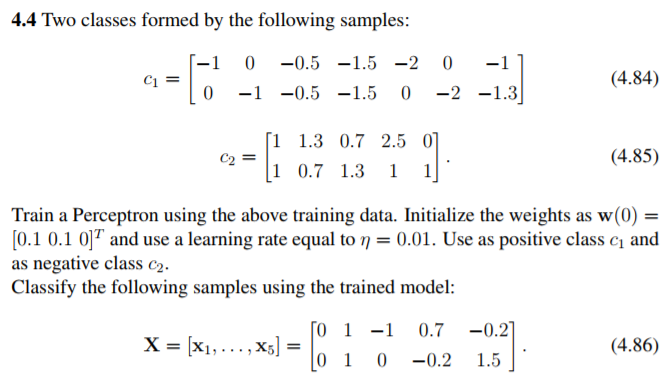

c1 = [  -1 0 -0.5 -1.5 -2 0 -1;
        0 -1 -0.5 -1.5 0 -2 -1.3]

c1 =    -1.0000         0   -0.5000   -1.5000   -2.0000         0   -1.0000
         0   -1.0000   -0.5000   -1.5000         0   -2.0000   -1.3000


[k,NC(1)] = size(c1);

c2 = [  1 1.3 0.7 2.5 0;
        1 0.7 1.3 1 1]

c2 =     1.0000    1.3000    0.7000    2.5000         0
    1.0000    0.7000    1.3000    1.0000    1.0000


[k,NC(2)] = size(c2);

K = 2;

## Perceptron Training

The *perceptron criterion function* is used to optimize the discriminant hyperplane, which discriminates the two classes. This is accomplished through an iterative process, where the weight vector *w* is adjusted each iteration until classes are adequately classified.

The adequacy of the classification depends on the separation of the classes. In this case the separation is good, so all samples should be correctly classified.

The algorithm requires the initialization of *weight* *w* and *learning rate* $\eta$. This is given by the exercise as:

$w=\left\lbrack \begin{array}{c}
0\ldotp 1\\
0\ldotp 1
\end{array}\right\rbrack \text{ }$(add a zero for the augmented samples)


$$\eta =0\ldotp 01$$


The algorithm then goes through iterative steps to optimize the hyperplane, by optimizing the *weight* *w*, so that all samples are correctly classified. This requires a method to evaluate a method for evaluating the current classification of samples. For this purpose an evaluation function is defined:


$$f\left({\mathit{\mathbf{w}}}^\ast  ,x_i \right)=l_i w^{\ast T} x_i \ge 0\text{    },\text{  }i=1,\ldotp \ldotp \ldotp ,N$$


Where $l_i$ is the label of the correct class for the training sample. For binary classification cases it is common to use a positive and a negative class. For this exercise $c_{1\text{ }}$is defined as *positive* and $c_2$ is defined as negative.

Thus, if the value of $f\left({\mathit{\mathbf{w}}}^\ast  ,x_i \right)$is smaller than 0, the class has been wrongly classified.


$$f\left({\mathit{\mathbf{w}}}^\ast  ,x_i \right)<0\Longrightarrow \mathrm{misclassification}$$


All misclassified samples are added to the set $X$.


$$f\left({\mathit{\mathbf{w}}}^\ast  ,x_i \right)<0\Longrightarrow x_i \longrightarrow X\text{ }$$


The weight *w* is then updated based on the *learning rate *$\eta$ and the misclassified set $X\text{ }$ by:


$$w\longleftarrow w+\eta \ast \Sigma {\text{ }}_{x_i \in X\text{ }} l_i x_i$$


This continues until the misclassified set $X\text{ }$is empty, or the maximum number of allowed iterations is reached.

Since the goal is to train the discriminant fucntion $g\left(x\right)$, we augment the vectors *x *and *w*. The generalized linear decision function has the form:


$$g\left(x\right)=w_0 +\sum_{d=1}^{D} w_d x_d$$


By augmenting the vectors *x* and *w*, such that:


$$\tilde{x} \gets {\left\lbrack {1\text{ }x}^T \right\rbrack }^T$$



$$\tilde{w} ={\left\lbrack w_0 \text{ }w\right\rbrack }^T$$


The linear discriminant function may be calculated by:


$$g\left(x\right)=w^T x$$


% OBS: The sample vectors must be augmented
X = [c1 c2];
X = [ones(1,size(X,2)); X];  % Augmented sample vectors
[k,NX] = size(X);

% Initialize algorithm
% weights (dimension must correspond to size dimension of samples
w0 = [0 0.1 0.1]' % augmented weights

w0 =          0
    0.1000
    0.1000


% Learning rate
eta = 0.01

eta = 0.0100

% Class labels
c1_label = 1;
c2_label = -1;
labels = [ones(size(c1,2),1)*c1_label; ones(size(c2,2),1)*c2_label];

% Perform iterative algorithm
max_iter = 20;
w = w0;
for i=1:max_iter
    disp(['Perceptron training: iteration ', num2str(i)])
    class_err = [];
    correct_label = [];
    
    % Determine misclassified data
    for j=1:NX
        f_eval = labels(j)*(w'*X(:,j));
        if f_eval < 0
            class_err = [class_err X(:,j)];
            correct_label = [correct_label labels(j)];
        end
    end
    misclass_samples = size(class_err,2);
    disp(['# of misclassified samples: ', num2str(misclass_samples)])
    
    % Evaluate whether all samples are correctly classified, if not continue
    if misclass_samples==0  
        disp('All samples correctly classified')
        break;  
    end
    
    % Update the weight w based on misclassified data
    err_summation = zeros(k,1);
    for j=1:misclass_samples
        err_summation = err_summation + correct_label(j)*class_err(:,j);
    end
    w = w + eta*err_summation   
end

Perceptron training: iteration 1


# of misclassified samples: 12


w =     0.0200
   -0.0150
   -0.0130


Perceptron training: iteration 2


# of misclassified samples: 1


w =     0.0100
   -0.0150
   -0.0230


Perceptron training: iteration 3


# of misclassified samples: 0


All samples correctly classified


## Testing of Trained Discrimiant

The trained hyperplane can be used to calculate the discriminant function $g\left(w,x_i \right)$;


$$g\left(w,x\right)=w^T x$$


Which is valid when *x *and *w* are augmented:


$$\tilde{x} \gets {\left\lbrack {1\text{ }x}^T \right\rbrack }^T$$



$$\tilde{w} ={\left\lbrack w_0 \text{ }w\right\rbrack }^T$$


X = [0 1 -1 0.7 -0.2;
    0 1 0 -0.2 1.5]

X =          0    1.0000   -1.0000    0.7000   -0.2000
         0    1.0000         0   -0.2000    1.5000


X = [ones(1,size(X,2)); X];  % Augmented sample vectors
[k,NX] = size(X);

The discrimant function $g\left(w,x_i \right)$ can be used to classify the samples, by:


$$\begin{array}{l}
g\left(w,x_i \right)>0\Longrightarrow c_1 \\
g\left(w,x_i \right)<0\Longrightarrow c_2 \\
g\left(w,x_i \right)=0\Longrightarrow \mathrm{ambiguous}
\end{array}$$


g = zeros(NX,1)';
class = g';
for i=1:NX
    g(i) = w' * X(:,i);
    
    if(g(i)>0)
        class(i) = 1;
    elseif(g(i)<0)
        class(i) = 2;
    end
end
g

g =     0.0100   -0.0280    0.0250    0.0041   -0.0215


class

class =      1
     2
     1
     1
     2
